The walking robot variant of the assignment was chosen

**Side Shell Design**

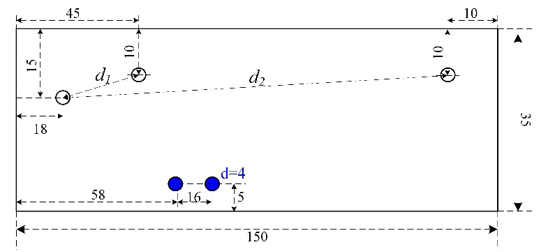

All dimensions are in **mm**:

% specify design parameters as vectors
d1_vec = (45 - 18) + (15 - 10) * 1i % from origin

d1_vec = 27.0000 + 5.0000i

d1 = abs(d1_vec)

d1 = 27.4591

d2_vec = (150 - 10 - 18) + (15 - 10) * 1i % from origin

d2_vec = 1.2200e+02 + 5.0000e+00i

d2 = abs(d2_vec)

d2 = 122.1024

## Design

syms a b c1 c2 p theta2(t)

[axioms, a_vec, b1_vec, b2_vec, c1_vec, c2_vec, p1_vec, p2_vec] = ...
    walking_robot_mechanics(d1_vec, d2_vec, a, b, c1, c2, p, theta2);

params2walking_robot = solve2fn( ...
    [a_vec, b1_vec, b2_vec, c1_vec, c2_vec, p1_vec, p2_vec], ... % solve for
    axioms, ... % using axioms
    [a, b, c1, c2, p, theta2]... % in terms of
);

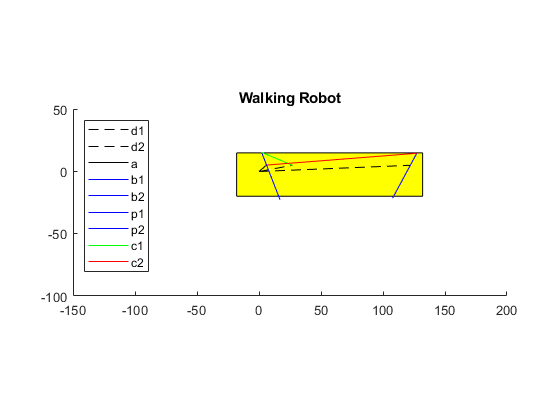

% change design parameters to see output
a =8;
b = 11; % mm, |b1| = |b2|
p = 30; % mm, |p1| = |p2|
c1 =27;
c2 =121.5;

ensure_gcrr(a, b, c1, d1); % front
ensure_gcrr(a, c2, b, d2); % back

animate_walking_robot( ...
    @(theta2) params2walking_robot(a, b, c1, c2, p, theta2), ...
    deg2rad(30) + angle(d1_vec), ...
    d1_vec, d2_vec);

## Analysis

% Define chosen design
a = 8;
b = 11;
p = 30;
c1 = 27;
c2 = 121.5;

% do the geometric calcuations
[axioms, a_vec, b1_vec, b2_vec, c1_vec, c2_vec, p1_vec, p2_vec, ...
    theta3_front, theta4_front, theta3_back, theta4_back] = ...
    walking_robot_mechanics(d1_vec, d2_vec, a, b, c1, c2, p, theta2);

% declare angular velocities
syms omega2(t) omega3_front(t) omega4_front(t) omega3_back(t) omega4_back(t)

% axioms diffed once (velocity analysis)
d_axioms = subs(diff(axioms), [ ...
    diff(theta2)
    diff(theta3_front)
    diff(theta4_front)
    diff(theta3_back)
    diff(theta4_back)
], [ ...
    omega2
    omega3_front
    omega4_front
    omega3_back
    omega4_back
]);

% declare angular acceleration
syms alpha2(t) alpha3_front(t) alpha4_front(t) alpha3_back(t) alpha4_back(t)

% axioms diffed twice (acceleration analysis)
dd_axioms = subs(diff(d_axioms), [ ...
    diff(omega2)
    diff(omega3_front)
    diff(omega4_front)
    diff(omega3_back)
    diff(omega4_back)
], [ ...
    alpha2
    alpha3_front
    alpha4_front
    alpha3_back
    alpha4_back
]);

M_vel = subs( ...
    diff(a_vec + p1_vec), ...
    [diff(theta2), diff(theta3_front)], ...
    [omega2, omega3_front]);

N_vel = subs( ...
    diff(d2_vec + p2_vec), ...
    [diff(theta4_back)], ...
    [omega4_back]);

$$N\_vel(t) = -30\,{\mathrm{e}}^{\theta_{4,\mathrm{back}}\left(t\right)\,\mathrm{i}}\,\omega_{4,\mathrm{back}}\left(t\right)\,\mathrm{i}$$


solving_for = [theta2 - angle(d2_vec), ... % back-leg internal theta2 angle (phi2)
    theta3_front, theta4_front, theta3_back, theta4_back, ... % other angles
    omega3_front, omega4_back, ... % front & back-leg angular velocities
    M_vel, N_vel, ... % feet velocities
    alpha3_front, alpha4_back % front & back-leg angular accelerations
];

% solve the system in terms of theta2, omega2 and alpha2
system = solve2fn(solving_for, [axioms d_axioms dd_axioms], [alpha2 omega2 theta2]);

alpha2 = 2; omega2 = 2;
vpa(system(alpha2_rad, omega2_rad, deg2rad(30) + angle(d1_vec)), 4) % theta2 = 30 deg

$$ans = \left(\begin{array}{ccccccccccc} 0.6657 & 1.941+2.498e-16\,\mathrm{i} & 2.744 & 0.0782-4.966e-16\,\mathrm{i} & 1.077 & -1.805 & 1.017 & -60.88-7.427\,\mathrm{i} & 26.87-14.46\,\mathrm{i} & -1.805 & 1.017 \end{array}\right)$$

vpa(system(alpha2_rad, omega2_rad, deg2rad(90) + angle(d1_vec)), 4) % theta2 = 90 deg

$$ans = \left(\begin{array}{ccccccccccc} 1.713 & 1.13-3.192e-16\,\mathrm{i} & 2.647 & 0.06514-5.031e-16\,\mathrm{i} & 1.773 & -1.135+4.017e-16\,\mathrm{i} & 1.458 & -46.52+11.61\,\mathrm{i} & 42.85+8.806\,\mathrm{i} & -1.135+4.017e-16\,\mathrm{i} & 1.458 \end{array}\right)$$

function theta4 = freudenstein(a, b, c, d_vec, theta2)
    d = norm(d_vec);
    theta1 = angle(d_vec);
    
    % first intermediaries
    k1 = d / a;
    k2 = d / c;
    k3 = (a^2 - b^2 + c^2 + d^2) / (2*a*c);
    
    % equation assumes that theta1 == 0. Subtract it here and add it later
    theta2_rot = theta2 - theta1;
    
    % second intermediaries
    A = cos(theta2_rot) - k1 - k2 * cos(theta2_rot) + k3;
    B = -2 * sin(theta2_rot);
    C = k1 - (k2 + 1) * cos(theta2_rot) + k3;
    
    % assume open configuration
    theta4 = 2 * atan((-B - sqrt(B^2 - 4*A*C)) / (2*A)) + theta1;
end

function ensure_gcrr(a, b, c, d)
    % ensure desired Barker classification - GCRR
    link_lens = [a, b, c, d];
    s = min(link_lens);
    l = max(link_lens);
    p_and_q = link_lens(~(link_lens == s | link_lens == l));
    
    is_grashof = (s + l) < sum(p_and_q);
    
    is_gcrr = is_grashof & s == link_lens(1);
    
    if (~is_gcrr)
        error("Fourbar must be GCRR. Got: " + mat2str(link_lens));
    end
end

function [nested, args] = nest_symbolic_args(expr)
    if isequal(class(expr),'symfun')
        args = argnames(expr);
        % unsure if this will work for multiple arguments, probably not -
        % revisit this when that happens.
        nested = expr(args);
    else
        nested = expr;
        args = [];
    end
end

function solutions = solve_for(symbols, axioms, in_terms_of)
    
    [symbols , symbols_args] = nest_symbolic_args(symbols);
    
    % symbols found in all axioms
    variable_syms = setdiff(symvar(axioms), symbols_args);
    % note that doesn't include symbolic functions. In order to use solve,
    % we have to convert symbolic functions into regular symbols and use
    % substitution on the axioms. Let's do it!
    axiom_sym_funcs = findSymType(axioms, 'symfun');
    if exist('in_terms_of','var') % keep any variable terms desired
        in_terms_of = nest_symbolic_args(in_terms_of);
        variable_syms = setdiff(variable_syms, in_terms_of);
        axiom_sym_funcs = setdiff(axiom_sym_funcs, in_terms_of);
    end
    
    axiom_sym_func_syms = sym('sym_func', size(axiom_sym_funcs));
    
    % do symbolic solve
    solved_vals = struct2array(solve( ...
        subs(nest_symbolic_args(axioms), axiom_sym_funcs, axiom_sym_func_syms), ...
        [variable_syms, axiom_sym_func_syms]));
    
    solutions = subs(symbols, [variable_syms, axiom_sym_funcs], solved_vals);
end

function optimized = solve2fn(sym_expr, axioms, in_terms_of)
    in_terms_of = nest_symbolic_args(in_terms_of);
    solutions = solve_for(sym_expr, axioms, in_terms_of);
    args = sym('arg', size(in_terms_of));
    for idx = 1:length(args)
        term_str_parts = split(string(in_terms_of(idx)), '(');
        term_name = term_str_parts{1};
        args(idx) = sym(term_name);
    end
    optimized = matlabFunction(subs(solutions, in_terms_of, args));
end

function animate_walking_robot(links_by_theta2, theta2_vals, d1_vec, d2_vec)
    figure;
    hold on;
    axis equal;
    title("Walking Robot");
    xlim([-150, 200])
    ylim([-100, 50])
    d1_x = real(d1_vec); d1_y = imag(d1_vec);
    d2_x = real(d2_vec); d2_y = imag(d2_vec);
    
    rectangle('Position', [-18, -(35 - 15), 150, 35], 'FaceColor', 'y')
    plot([0, d1_x], [0, d1_y], 'k--');
    plot([0, d2_x], [0, d2_y], 'k--');
    link_lines = [
        animatedline('Color', 'k') % a
        animatedline('Color', 'b') % b1
        animatedline('Color', 'b') % b2
        animatedline('Color', 'b') % p1
        animatedline('Color', 'b') % p2
        animatedline('Color', 'g') % c1
        animatedline('Color', 'r') % c2
    ];
    p1_locus = animatedline('Color', 'm', 'LineStyle', ':');
    p2_locus = animatedline('Color', 'm', 'LineStyle', ':');
    legend('d1', 'd2', 'a', 'b1', 'b2', 'p1', 'p2', 'c1', 'c2', 'Location', 'northwest');
    
    for theta2 = theta2_vals
        
        links = links_by_theta2(theta2);
        
        % clear all link_lines
        arrayfun(@clearpoints, link_lines)
        
        % unpack vectors
        a = links(1);
        b1 = links(2);
        b2 = links(3);
        c1 = links(4);
        c2 = links(5);
        p1 = links(6);
        p2 = links(7);
        
        a_x = real(a); a_y = imag(a);
        
        p1_tip = [a_x + real(p1), a_y + imag(p1)];
        p2_tip = [d2_x + real(p2), d2_y + imag(p2)];
        
        % there has to be a better way to restructure all of this
        addpoints(link_lines(1), [0, a_x], [0, a_y]) % a
        addpoints(link_lines(2), [a_x, a_x + real(b1)], [a_y, a_y + imag(b1)]) % b1
        addpoints(link_lines(3), [d2_x, d2_x + real(b2)], [d2_y, d2_y + imag(b2)]) % b2
        addpoints(link_lines(4), [a_x, p1_tip(1)], [a_y, p1_tip(2)]) % p1
        addpoints(link_lines(5), [d2_x, p2_tip(1)], [d2_y, p2_tip(2)]) % p2
        addpoints(link_lines(6), [d1_x, d1_x + real(c1)], [d1_y, d1_y + imag(c1)]) % c1
        addpoints(link_lines(7), [a_x, a_x + real(c2)], [a_y, a_y + imag(c2)]) % c2
        
        addpoints(p1_locus, p1_tip(1), p1_tip(2));
        addpoints(p2_locus, p2_tip(1), p2_tip(2));
        
        drawnow;
    end
    hold off;
end

function [axioms, a_vec, b1_vec, b2_vec, c1_vec, c2_vec, p1_vec, p2_vec, ...
    theta3_front_, theta4_front_, theta3_back_, theta4_back_] = ...
    walking_robot_mechanics(d1_vec, d2_vec, a, b, c1, c2, p, theta2)

    % driving link
    a_vec = a * exp(1i * theta2); 

    % front-leg links
    syms theta3_front(t) theta4_front(t)
    theta3_front_ = theta3_front; % export symbols
    theta4_front_ = theta4_front;
    b1_vec = b * exp(1i * theta3_front); % from a
    c1_vec = c1 * exp(1i * theta4_front); % from d1
    p1_vec = p * exp(1i * (pi + theta3_front)); % from a

    % back-leg links
    syms theta3_back(t) theta4_back(t)
    theta3_back_ = theta3_back; % export symbols
    theta4_back_ = theta4_back; 
    c2_vec = c2 * exp(1i * theta3_back); % from a
    b2_vec = b * exp(1i * theta4_back); % from d2
    p2_vec = p * exp(1i * (pi + theta4_back)); % from d2
    
    axioms = [
        % front-leg vectorloop equation
        a_vec + b1_vec == d1_vec + c1_vec
        % front-leg freudenstein equation
        theta4_front == freudenstein(a, b, c1, d1_vec, theta2)
        
        % back-leg vectorloop equation
        a_vec + c2_vec == d2_vec + b2_vec
        % back-leg freudenstein equation
        theta4_back == freudenstein(a, c2, b, d2_vec, theta2)];
end